# Introducing ISET3d calculations

Renders a scene containing a sphere to illustrate the basic read, edit, write cycle.

**See also:**

    t_piIntro_*, piRecipeDefault, @recipe

## Initialize ISET and Docker

Start up ISET and check that docker is configured 

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the recipe

thisR = piRecipeDefault('scene name','sphere');

Read 1 materials.
Read 0 textures.
***Scene parsed.


The recipe has many fields that control the scene properties how it is rendered.  We simply list them here.  A lot of this wiki describes how to set and get properties from the many slots ISET3d recipe slots.

thisR

thisR =   recipe with properties:

            camera: [1×1 struct]
           sampler: [1×1 struct]
              film: [1×1 struct]
            filter: []
        integrator: [1×1 struct]
          renderer: []
            lookAt: [1×1 struct]
             scale: [0×3 double]
             world: {'WorldBegin'}
            lights: []
    transformTimes: []
         inputFile: '/Users/wandell/Documents/MATLAB/iset3d-v4/data/V4/sphere/sphere.pbrt'
        outputFile: '/Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/sphere.pbrt'
      renderedFile: ''
           version: 4
         materials: [1×1 struct]
          textures: [1×1 struct]
            assets: [1×1 tree]
          exporter: 'C4D'
             media: []
          metadata: [1×1 struct]
         recipeVer: 2
           verbose: 2


## Edit the recipe

For example, we can place a point light in the sphere scene.  Without a light, the scene will appear black!

pointLight = piLightCreate('point','type','point','cameracoordinate', true);
thisR.set('light',pointLight, 'add');

We can also set rendering properties.

thisR.set('film resolution',[192 192]);
thisR.set('rays per pixel',128);
thisR.set('n bounces',1); % Number of bounces
thisR.set('render type', {'radiance', 'depth'});

## Write the recipe, render it, and show it

piWrite(thisR);

In this example, we use a pinhole camera.  Thus, we are rendering the scene radiance.  If we include a lens, we would be rendering an optical image.

[scene, result] = piRender(thisR);

 Rsync Put: rsync -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/
Pushed scene to remote in:   0.58
Render: docker --context wandell-v4 exec -it  pbrt-gpu-wandell4190 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt"
Successfuly rendered remotely in:   2.81
 Rsync Pull: rsync -r wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/renderings
Retrieved output in:   0.54
Complete render took: 4.85e+00 seconds.*** Rendering time for sphere:  4.9 sec ***



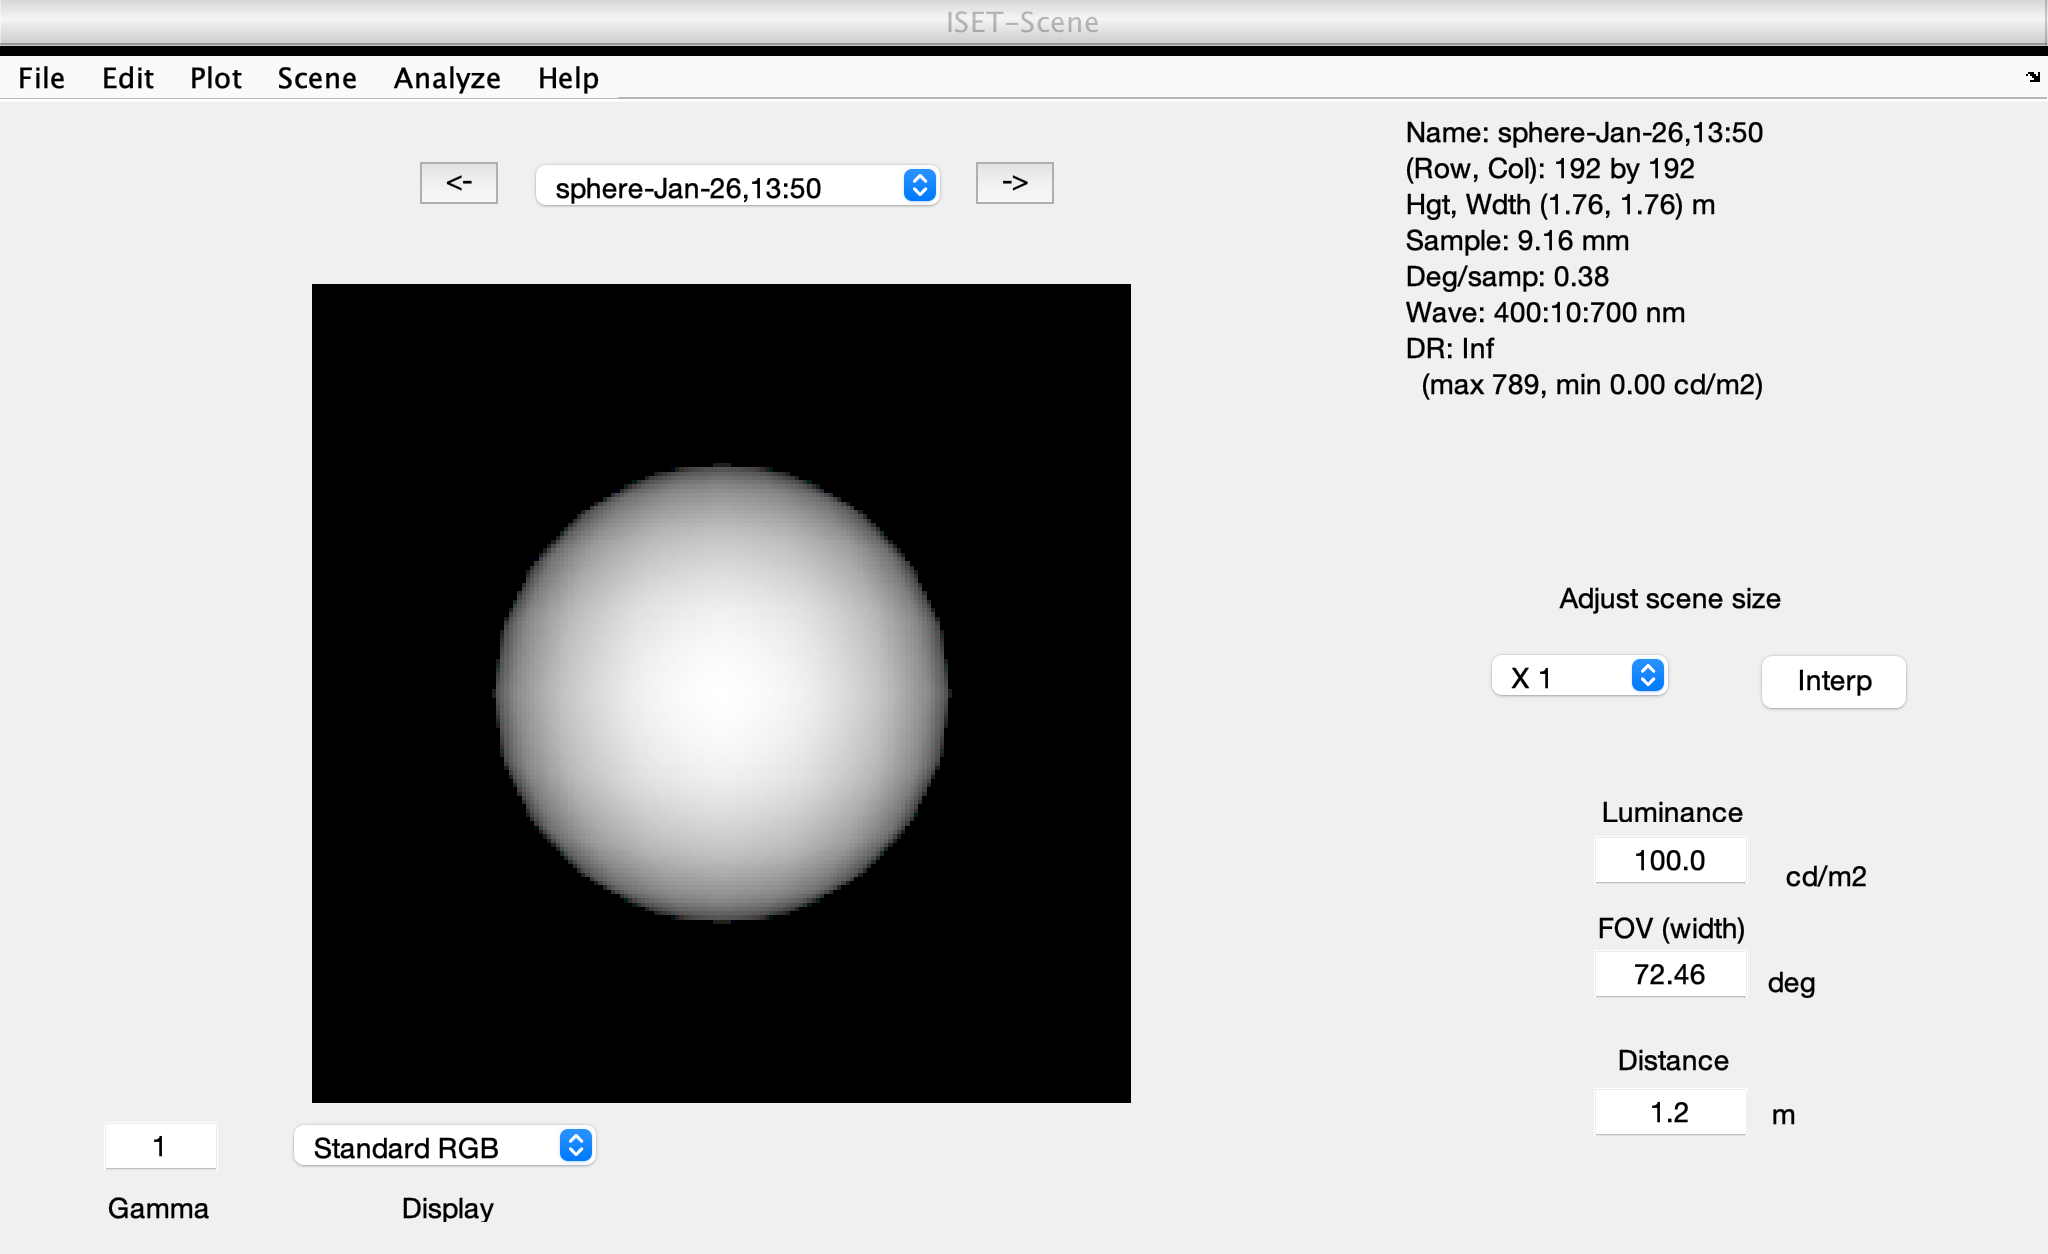

sceneWindow(scene);

## By default, piRender computes the scene or oi depth map

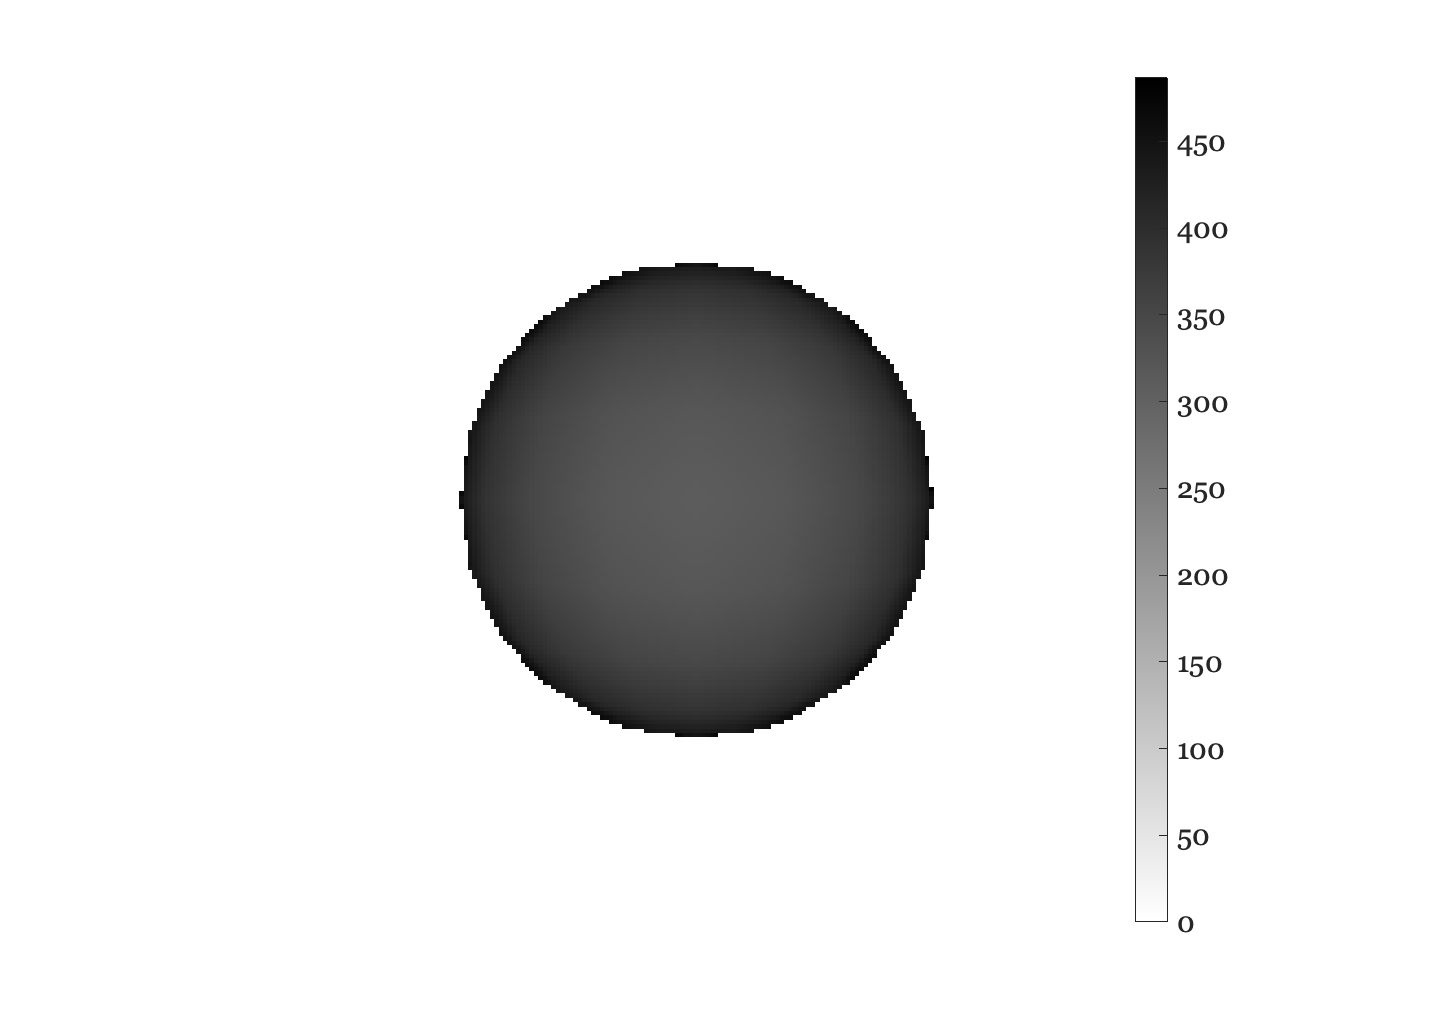

scenePlot(scene,'depth map');

## Change the light to a bluish light

You can edit the lights this way, adding a light which is more blue and distant 

distantLight = piLightCreate('distant','type','distant',  'spd', [9000],  'cameracoordinate', true);
thisR.set('light',pointLight.name, 'delete');
thisR.set('light',distantLight, 'add');

This is an efficient way to Write, Render and Show without the separate calls.

 Rsync Put: rsync -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/
Pushed scene to remote in:   0.55
Render: docker --context wandell-v4 exec -it  pbrt-gpu-wandell4190 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt"
Successfuly rendered remotely in:   2.73
 Rsync Pull: rsync -r wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/renderings
Retrieved output in:   0.62
Complete render took: 4.61e+00 seconds.*** Rendering time for sphere:  4.6 sec ***



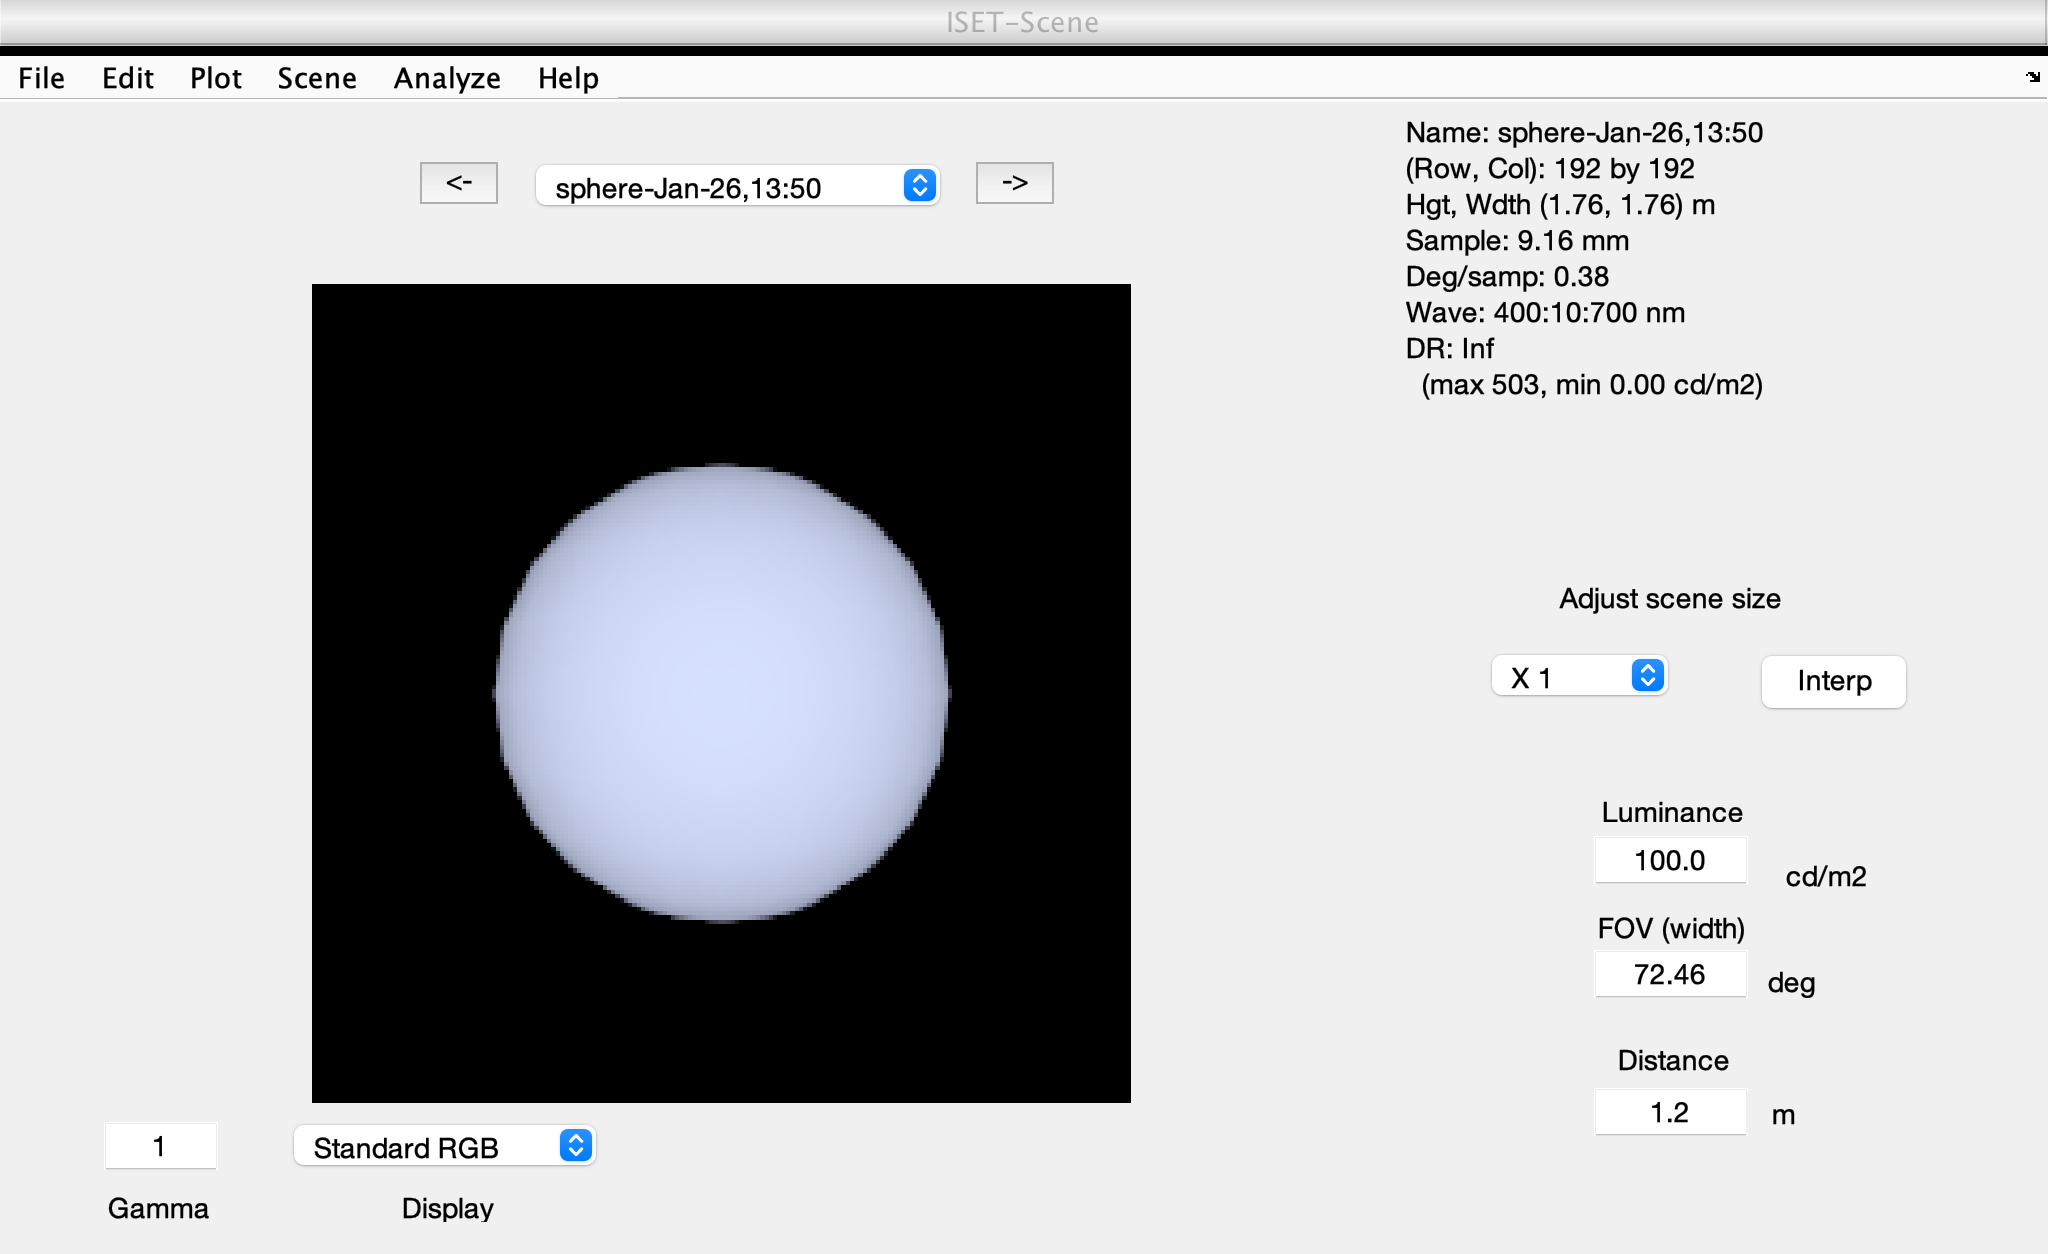

scene = piWRS(thisR);

## Read an  FBX file and write it as PBRT

% FBX is converted into PBRT
fbxFile = fullfile(piRootPath,'data','V4','teapot-set','TeaTime.fbx');
 
thisR  = piRead(fbxFile);

Converting FBX file into PBRT file...
Formating PBRT file...
Copying /Users/wandell/Documents/MATLAB/iset3d-v4/data/V4/teapot-set/TeaTime-converted.pbrt
Copying /Users/wandell/Documents/MATLAB/iset3d-v4/data/V4/teapot-set/TeaTime.fbx
Copying /Users/wandell/Documents/MATLAB/iset3d-v4/data/V4/teapot-set/license.txt
Copied resources from:
/Users/wandell/Documents/MATLAB/iset3d-v4/data/V4/teapot-set 
to 
/Users/wandell/Documents/MATLAB/iset3d-v4/local/formatted/TeaTime-converted 
 
ISET3d-TeaTime-converted-5197
Read 6 materials.
Read 1 textures.
Normal Map: textures/Metal13_nrm.png is converted 
Normal Map: textures/Wood02_nrm.png is converted 
***Scene parsed.


Convert scene unit from centimeter to meter

thisR.set('film resolution',[600 600]/2);
thisR.set('rays per pixel',32);


Set the render type.

One type is radiance, and here are the others

**rTypes = {'radiance','depth','both','all','coordinates','material','instance', 'illuminant','illuminantonly'};**

thisR.set('film render type',{'radiance','depth'});

%% move object
thisR.set('asset','Cylinder.001_B','world translation',[0.2 0 0]);

thisR.show('objects');

                                     material            positions (m)               sizes (m)        
                                 ________________    _____________________    ________________________

    0006ID_001_Cylinder.001_O    {'Stone'       }    {'6.39 5.47 16.50'  }    {'NaN NaN NaN'         }
    0008ID_002_Cylinder.001_O    {'Rubber'      }    {'6.39 5.47 16.50'  }    {'NaN NaN NaN'         }
    0010ID_003_Cylinder.001_O    {'Porcelain'   }    {'6.39 5.47 16.50'  }    {'NaN NaN NaN'         }
    0012ID_004_Cylinder.001_O    {'Wood'        }    {'6.59 5.47 16.50'  }    {'NaN NaN NaN'         }
    0015ID_001_Cylinder.004_O    {'Stone'       }    {'-8.18 5.47 11.67' }    {'NaN NaN NaN'         }
    0017ID_002_Cylinder.004_O    {'Rubber'      }    {'-8.18 5.47 11.67' }

## Add a light

 Rsync Put: rsync -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/TeaTime/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/TeaTime/
Pushed scene to remote in:   0.71
Render: docker --context wandell-v4 exec -it  pbrt-gpu-wandell4190 sh -c "cd /iset/iset3d-v4/local/TeaTime && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/TeaTime.exr TeaTime.pbrt"
Successfuly rendered remotely in:   3.71
 Rsync Pull: rsync -r wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/TeaTime/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/TeaTime/renderings
Retrieved output in:   1.06
Complete render took: 6.38e+00 seconds.*** Rendering time for TeaTime:  6.4 sec ***



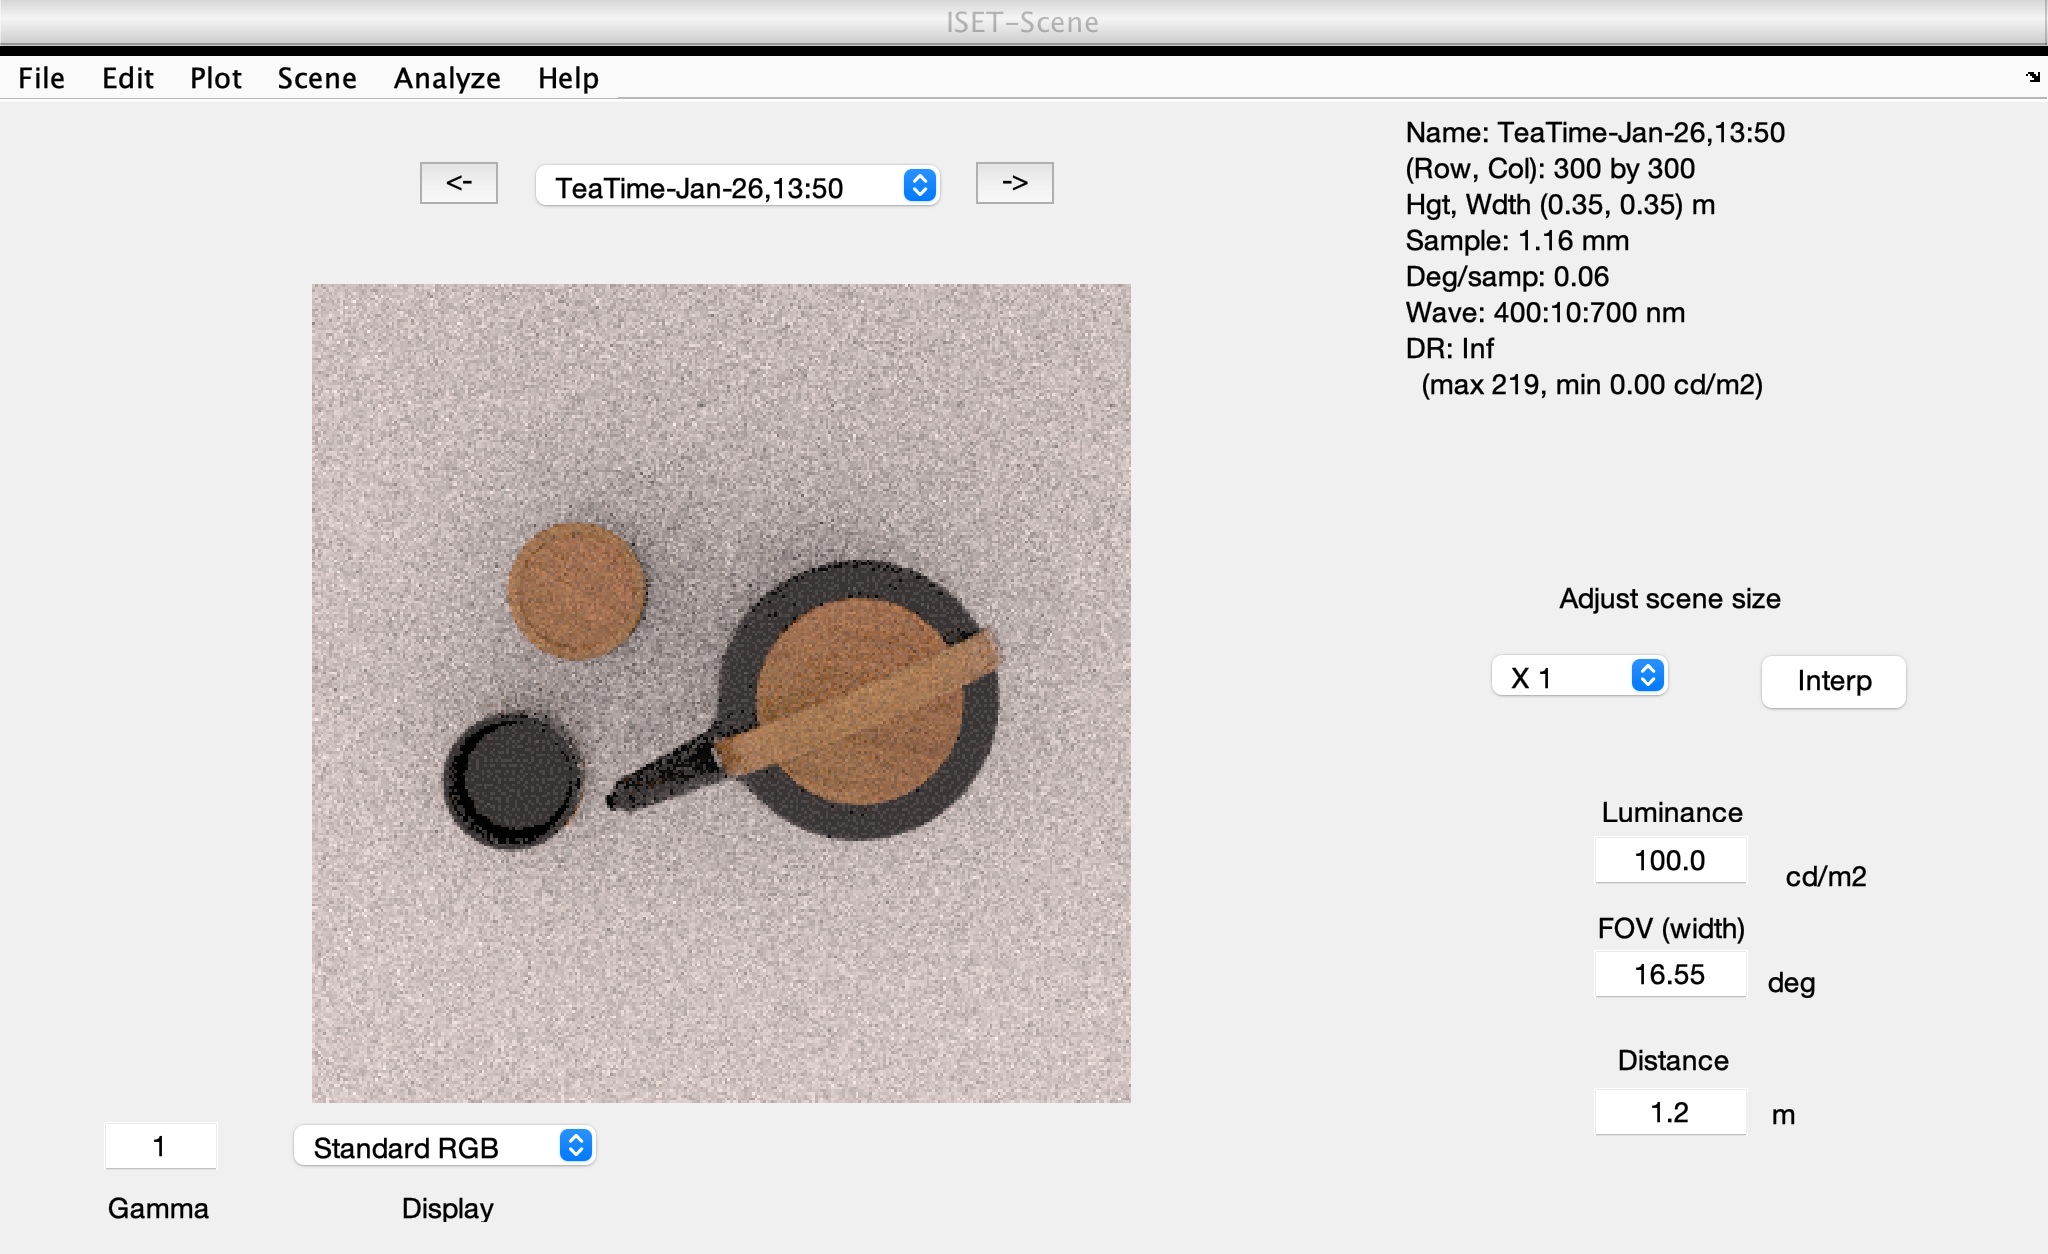

piLightDelete(thisR, 'all'); 
lightName = 'new light';
newLight = piLightCreate(lightName,...
                        'type','infinite',...
                        'spd',[0.4 0.3 0.3],...
                        'specscale',1);
thisR.set('light', newLight, 'add');

% Render and return the scene
scene = piWRS(thisR);

Show the geometry

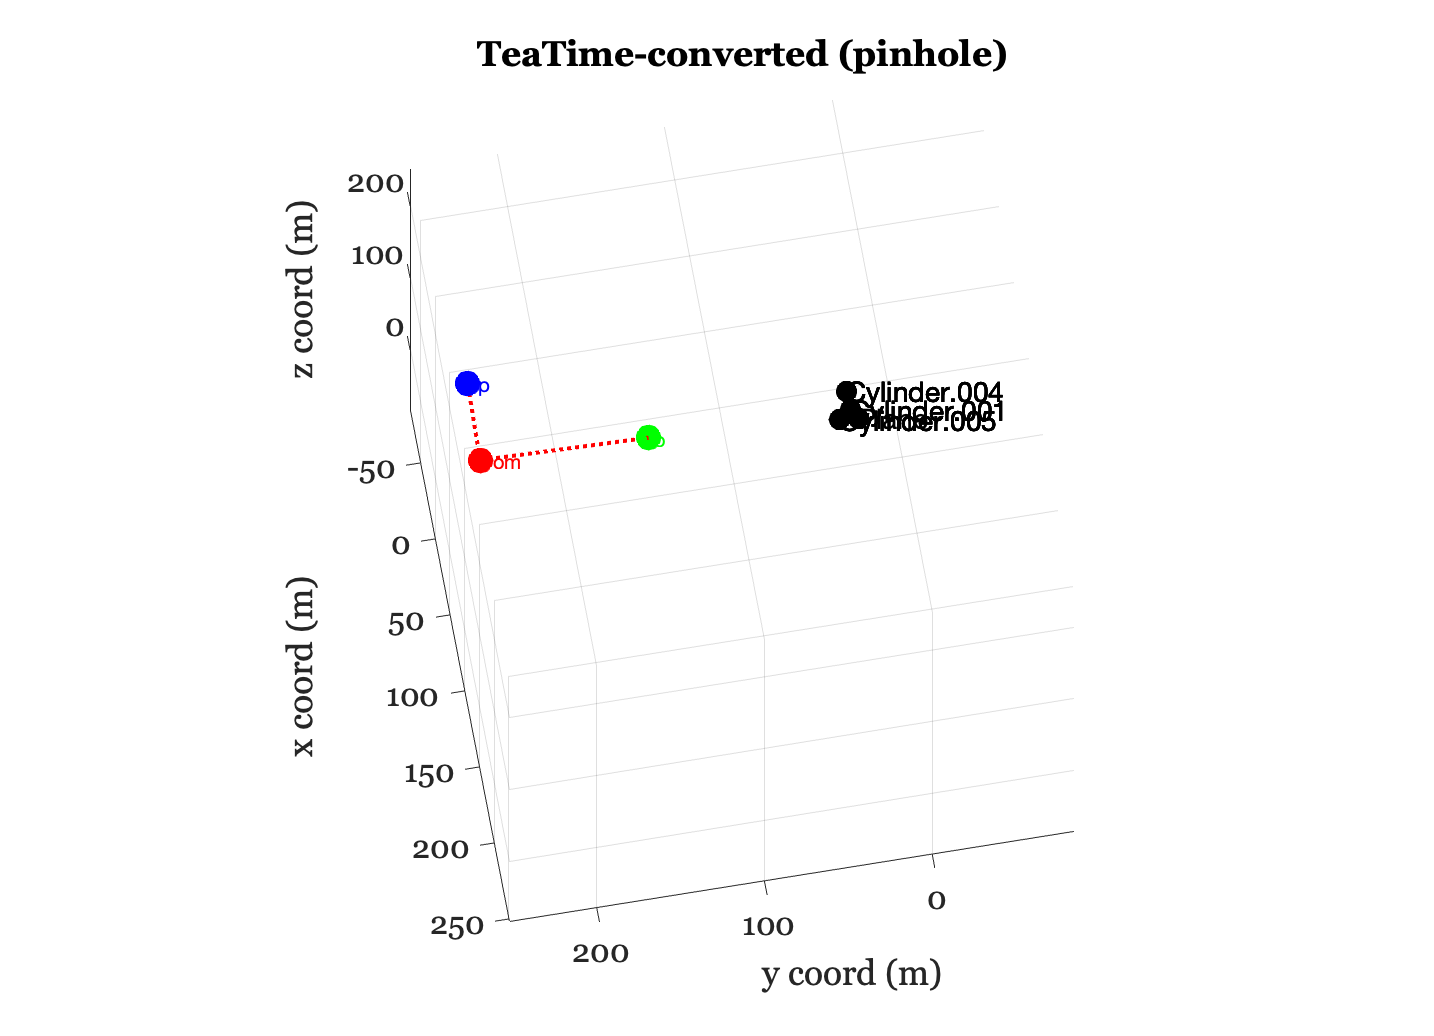

piAssetGeometry(thisR);view(-80,-65);